p = [0.0006	-0.0646	-0.3964]

p =     0.0006   -0.0646   -0.3964



ratios = [.5 1 2 4]

ratios =     0.5000    1.0000    2.0000    4.0000



figure;

for ratio = ratios
    f = @(t_in,omega_in) (p(1)*omega_in^2 + p(2)*omega_in + p(3))/ratio;
    [ode45_t_list, ode45_freq_list] = ode45(f, [0, 100], freq_list(1))
    plot(ode45_t_list, ode45_freq_list); hold on;
end

ode45_t_list =          0
    0.5132
    1.0263
    1.5395
    2.0526
    4.5526
    7.0526
    9.5526
   12.0526
   13.3436


ode45_freq_list =    41.8650
   39.7781
   37.7270
   35.7162
   33.7497
   24.9111
   17.4602
   11.4658
    6.8227
    4.8798


ode45_t_list =          0
    1.0263
    2.0526
    3.0789
    4.1053
    6.6053
    9.1053
   11.6053
   14.1053
   16.6053


ode45_freq_list =    41.8650
   39.7781
   37.7270
   35.7162
   33.7497
   29.1670
   24.9103
   21.0068
   17.4689
   14.2958


ode45_t_list =          0
    2.0526
    4.1053
    6.1579
    8.2105
   10.7105
   13.2105
   15.7105
   18.2105
   20.7105


ode45_freq_list =    41.8650
   39.7781
   37.7270
   35.7162
   33.7497
   31.4199
   29.1670
   26.9959
   24.9104
   22.9135


ode45_t_list =          0
    2.5000
    5.0000
    7.5000
   10.0000
   12.5000
   15.0000
   17.5000
   20.0000
   22.5000


ode45_freq_list =    41.8650
   40.5901
   39.3278
   38.0792
   36.8453
   35.6270
   34.4252
   33.2407
   32.0744
   30.9270


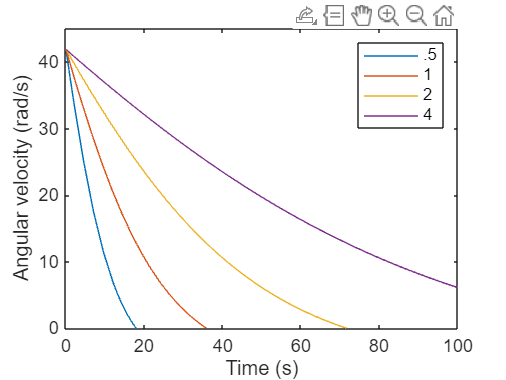


axis([0 100 0 45])
legend('.5', '1', '2', '4')
xlabel("Time (s)")
ylabel("Angular velocity (rad/s)")